# Takeoff Requirements

## 500 m Runway

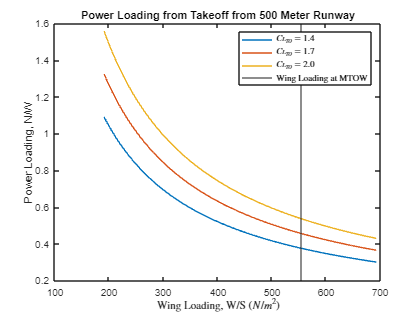

clc

S_to1 = 500;     %in meters, maximum field length in CS-22
S_tog2 = 250;    %in meters, short takeoff goal
rho1=1.1901;     %kg/m^3, air density at airport altitude
sigma1=1.1901/1.225;  %atmospheric density ratio
CL_max_TO=linspace(1.4,2.0,3);  %Max takeoff CL from Roskam pg. 91
W_to=990;        %kg, initial estimate of takeoff weight
W_e=455;         %kg, initial estimate of empty weight
L_Dmax = 46.5;   % L/D max
A = 22.82;       % Aspect ratio
e_clean = .9;    % Oswald's efficiency factor in a clean configuration
eta_p = 0.8;     % Prop efficiency, based on modern high efficient props
S=17.53;         % in m^2, wing area of DG1000S (20m span), this is an estimate
W_S_MTOW = W_to*9.81/S; %Estimated maximum wing loading in N/m^2

S_tog1 = S_to1/1.66; %Takeoff distance in meters
TOP23_1 = 153;       %dimensionless, for S_to1
TOP23_2 = 85;        %dimensionless, for S_tog2

W_S_TO = linspace(.75*9.81*W_e/S,1.25*9.81*W_to/S,100);     %Estimated range of wing loadings, from .75*We to 1.25*MTOW

W_P_TO1_lowCL = TOP23_1*CL_max_TO(:,1)*sigma1./W_S_TO;
W_P_TO1_avgCL = TOP23_1*CL_max_TO(:,2)*sigma1./W_S_TO;
W_P_TO1_highCL = TOP23_1*CL_max_TO(:,3)*sigma1./W_S_TO;

figure(1)
plot(W_S_TO,W_P_TO1_lowCL,W_S_TO,W_P_TO1_avgCL,W_S_TO,W_P_TO1_highCL)
xline(W_S_MTOW)
title('Power Loading from Takeoff from 500 Meter Runway')
xlabel('Wing Loading, W/S $(N/m^2)$', 'Interpreter', 'latex'), ylabel('Power Loading, N/W')
legend('$C_{L_{TO}}=1.4$','$C_{L_{TO}}=1.7$','$C_{L_{TO}}=2.0$','Wing Loading at MTOW', 'Interpreter', 'latex')

## From 250 m

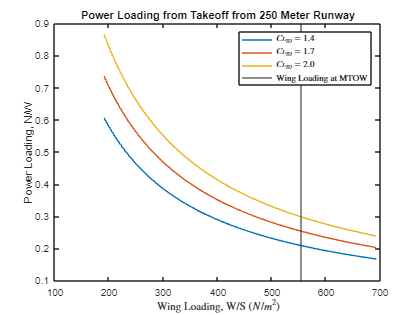

W_S_TO = linspace(.75*9.81*W_e/S,1.25*9.81*W_to/S,100);     %Estimated range of wing loadings, from .75*We to 1.25*MTOW

W_P_TO1_lowCL = TOP23_2*CL_max_TO(:,1)*sigma1./W_S_TO;
W_P_TO1_avgCL = TOP23_2*CL_max_TO(:,2)*sigma1./W_S_TO;
W_P_TO1_highCL = TOP23_2*CL_max_TO(:,3)*sigma1./W_S_TO;

figure(2)
plot(W_S_TO,W_P_TO1_lowCL,W_S_TO,W_P_TO1_avgCL,W_S_TO,W_P_TO1_highCL)
xline(W_S_MTOW)
xlabel('Wing Loading, W/S $(N/m^2)$', 'Interpreter', 'latex'), ylabel('Power Loading, N/W')
title('Power Loading from Takeoff from 250 Meter Runway')
legend('$C_{L_{TO}}=1.4$','$C_{L_{TO}}=1.7$','$C_{L_{TO}}=2.0$','Wing Loading at MTOW', 'Interpreter', 'latex')